clear all
% Color
set(0,'defaultTextInterpreter','latex');
%str1 = '#87CEFA';
str2 = '#FFB6C1';
str3 = '#d6d6d6';
str1 = '#ED3F00';
%str3 = '#C0C0C0';
%str3 = '#868686';
str4 = '#006400';
color1 = sscanf(str1(2:end),'%2x%2x%2x',[1 3])/255;
color2 = sscanf(str2(2:end),'%2x%2x%2x',[1 3])/255;
color3 = sscanf(str3(2:end),'%2x%2x%2x',[1 3])/255;

## True coordinate

[X,Y] = meshgrid(-5:.5:5);
Z = cos(X).*cos(Y).*exp(-sqrt(X.^2+Y.^2)/4);
x = X(:);
y = Y(:);
z = Z(:);
P = [x y z];
Pt= P';
p = Pt(:);
n = size(x,1); d=3; % m1 = 1000; d = 3; 
r = 1:n;
% Graph 
epsilon = 1;
[A,DistA,H] = proximityGraph(P,n,epsilon);
m = size(H,1);
% Network position in 3D

% Calculate bearing Laplacian
z = kron(H,eye(d))*p;
Z = reshape(z,d,length(H));
G = Z./vecnorm(Z);
g = G(:);
diagG = [];
for i=1:m
    diagG = blkdiag(diagG,G(:,i));
end
diagP = eye(m*d)-diagG*diagG';

Hbar = kron(H,eye(d));
Lb = Hbar'*diagP*Hbar;
(rank(Lb) - d*n + d + 1)

ans = 0


eig_max=max(eig(Lb));

## Randomized Gossip Update

Probability transition matrix

PDF = randStochasticMatrix(A); % Probability Distribution Function
CPDF = zeros(n,n-1);         % Cummulative Probability Distribution Function
for i=1:n
    for j=1:n
        if j<i
            CPDF(i,j) = sum(PDF(i,1:j));
        else
            if j>i
                CPDF(i,j-1) = sum(PDF(i,1:j));
            end
        end
    end
end

alpha = 0.3;
epsl = 0.05;

N = 30000;

% Initialization
est_p0 = p + 2.5*(rand(d*n,1)-0.5);
est_p = zeros(d*n,N);
est_p(:,1) = est_p0;
err = zeros(1,N); % Total bearing errors
err(1,1) = norm(Lb*est_p(:,1),2);
% Loop 
t_end = N;

%F(t_end) = struct('cdata',[],'colormap',[]);
% v = VideoWriter('sim2.avi');
% v.FrameRate = 24;
% open(v);

% figure(1); clf
% hold on
% 
% 
% subplot(2,2,1)
% hold on
% plot_realconfig
% 
% subplot(2,2,2)
% hold on
% plot_realconfig2

for k=1:N-1
   q1 = randi(n);
   r = rand(1);
   % and finds a neighbor for chatting
   q2 = find((CPDF(q1,:)>=r),1,'first'); 
   if q2>=q1
        q2=q2+1;
   end
   % The matched agents update
   for j1=1:n
       if j1==q1
            est_p(d*q1-d+1:d*q1,k+1) = est_p(d*q1-d+1:d*q1,k) - alpha*Lb(d*q1-d+1:d*q1,d*q2-d+1:d*q2)*(est_p(d*q2-d+1:d*q2,k)-est_p(d*q1-d+1:d*q1,k));
       else
           if j1==q2
                est_p(d*q2-d+1:d*q2,k+1) = est_p(d*q2-d+1:d*q2,k) - alpha*Lb(d*q1-d+1:d*q1,d*q2-d+1:d*q2)*(est_p(d*q1-d+1:d*q1,k)-est_p(d*q2-d+1:d*q2,k));
           else
                est_p(d*j1-d+1:d*j1,k+1) = est_p(d*j1-d+1:d*j1,k); % while the rest sleep
           end
       end
   end
   err(k+1) = norm(Lb*est_p(:,k+1),2); % The bearing error cannot increase, and eventually vanishes
   
   % figure(1);
%    if mod(k,50)==0
%    step = num2str(k);
%    
%    delete(subplot(2,2,3))
%    subplot(2,2,3)
%    %clf;
%    hold on;
%    plot_realconfig1(q1,q2,est_p(:,k),n,d);
%    title(strcat('Estimated configuration at k=',step));
   % drawnow
   
%    delete(subplot(2,2,4))
%    subplot(2,2,4)
%    % clf;
%    hold on;
%    plot(1:k,err(1,1:k),'-b','LineWidth',1.5);
%    title(strcat('Total bearing error at k=',step));
%    ylim([0,250])
%    if k<=10000
%       xlim([0,10000])
%    else
%        xlim([0,25000])
%    end
%    box on

%    drawnow
%    F = getframe(gcf);
%    writeVideo(v,F);
%    end
end

figure
plot_realconfig(H,n,m,p)

ans = 1

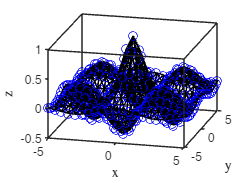

view(14,23)


figure
N=1;
plot_realconfig_N(H,n,m,est_p,N)

ans = 1

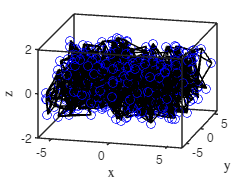

view(14,23)


figure
N=100;
plot_realconfig_N(H,n,m,est_p,N)

ans = 1

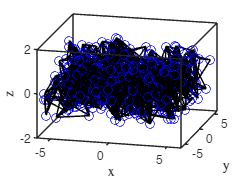

view(14,23)


figure
N=1000;
plot_realconfig_N(H,n,m,est_p,N)

ans = 1

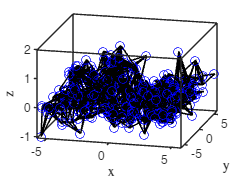

view(14,23)


figure
N=5000;
plot_realconfig_N(H,n,m,est_p,N)

ans = 1

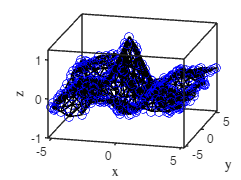

view(14,23)


figure
N=10000;
plot_realconfig_N(H,n,m,est_p,N)

ans = 1

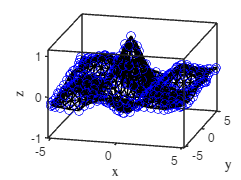

view(14,23)


figure
N=20000;
plot_realconfig_N(H,n,m,est_p,N)

ans = 1

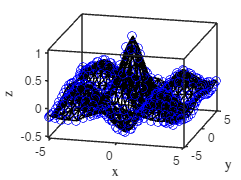

view(14,23)


figure
N=30000;
plot_realconfig_N(H,n,m,est_p,N)

ans = 1

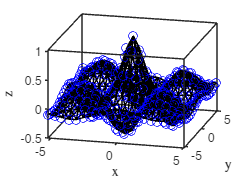

view(14,23)

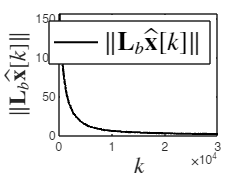


% 
N = 30000;
figure
plot(1:N,err(1,1:N),'-k','LineWidth',1.5);
xlabel('$k$','Interpreter','latex','FontSize',16)
ylabel('$\|\mathbf{L}_b\hat{\mathbf{x}}[k]\|$','Interpreter','latex','FontSize',16)
legend({'$\|\mathbf{L}_b\hat{\mathbf{x}}[k]\|$'},'Interpreter','latex','FontSize',18)

function [A,DistA,H] = proximityGraph(P,n,epsilon)
A = zeros(n,n);
H = [];
DistA = A;
m=0;
for i=1:n
    for j=i+1:n
        DistA(i,j) = norm(P(i,:)-P(j,:),2);
        if DistA(i,j)<=epsilon
            A(i,j)=1;
            H = [H;zeros(1,n)];
            m=m+1;
            H(m,i)=-1;H(m,j)=1;
        end
    end
end
A = A + A';
DistA = DistA + DistA';

end

function P = randStochasticMatrix(A)
% randomly create a random matrix with nonzero pattern the same as the
% (0,1)-adjacency input matrix A
rng(1)
n = size(A,1);
P = zeros(n,n);
for i=1:n
    for j=1:n
        if A(i,j)~=0
            P(i,j)=rand(1);
        end
    end
    P(i,:)=P(i,:)/sum(P(i,:));
end
end

function r = plot_realconfig(H,n,m,p)
figure;
hold on
range=1:n;
for k=1:m
index1 = range(H(k,:)<0); 
index2 = range(H(k,:)>0);
line([p(index1*3-2,1), p(index2*3-2,1)], [p(index1*3-1,1), p(index2*3-1,1)], [p(index1*3,1),p(index2*3,1)], 'Color', 'k', 'LineWidth', 1, 'LineStyle','-');
end

for i=1:n
plot3(p(3*i-2,1), p(3*i-1,1), p(3*i,1), 'ob');
end

ax = gca;
ax.BoxStyle = 'full';
box on
%title('Global positions of the sensors')
%view(-70,20)
xlabel x
ylabel y
zlabel z
r=1;
end

function r = plot_realconfig_N(H,n,m,est_p,N)
figure
hold on
range=1:n;
for k=1:m
index1 = range(H(k,:)<0); index2 = range(H(k,:)>0);
line([est_p(index1*3-2,N), est_p(index2*3-2,N)], [est_p(index1*3-1,N), est_p(index2*3-1,N)], [est_p(index1*3,N),est_p(index2*3,N)], 'Color', 'k', 'LineWidth', 1, 'LineStyle','-');
end
for i=1:n
    plot3(est_p(3*i-2,N), est_p(3*i-1,N), est_p(3*i,N), 'ob');
end
box on
%view(2)
ax = gca;
ax.BoxStyle = 'full';
% ax.XColor = color3;
% ax.YColor = color3;
% ax.ZColor = color3;
xlabel x
ylabel y
zlabel z
view(-70,20)
r=1;
end